## Wheel Position

The position of the wheel is given by integrating the wheel velocity with time 

data = readtable('data/matlab_table/data_active_pos_fb_response_only.xml');
summed_speeds = cumsum(data.wheel_speed,2,'omitmissing'); %sum over rows and ignore nans
num_speed_values = sum(~isnan(data.wheel_speed),2);


data.wheel_pos = summed_speeds ./ num_speed_values % NOTE ./ operator

data = 6923×6 table
    trial    mouse     session_date    response_time    wheel_speed      wheel_pos  
    _____    ______    ____________    _____________    ____________    ____________

      1      "Cori"    14-Dec-2016         1.1502       1×250 double    1×250 double
      2      "Cori"    14-Dec-2016         1.3995       1×250 double    1×250 double
      3      "Cori"    14-Dec-2016        0.94929       1×250 double    1×250 double
      4      "Cori"    14-Dec-2016         2.2668       1×250 double    1×250 double
      9      "Cori"    14-Dec-2016         2.0971       1×250 double    1×250 double
     10      "Cori"    14-Dec-2016         1.2497       1×250 double    1×250 double
     11      "Cori"    14-Dec-2016        0.85013       1×250 double    1×250 double
     12   



data.mean_wheel = mean( data.wheel_speed, 2, 'omitmissing');


Plot wheel position against time for a few trials

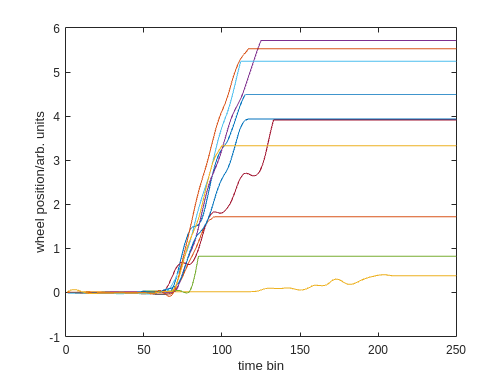

dd= data(data.mean_wheel>0, 'wheel_pos');
plot(dd{1:10, 'wheel_pos'}')
xlabel('time bin')
ylabel('wheel position/arb. units')

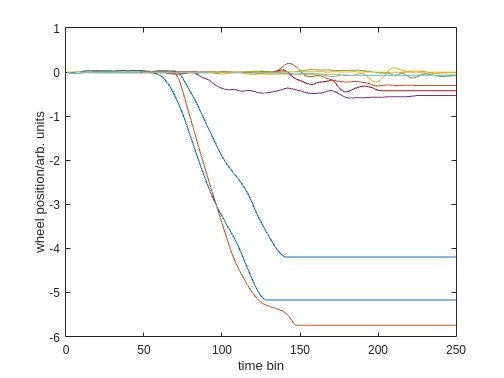


dd= data(data.mean_wheel<0, 'wheel_pos');
plot(dd{1:10, 'wheel_pos'}')
xlabel('time bin')
ylabel('wheel position/arb. units')

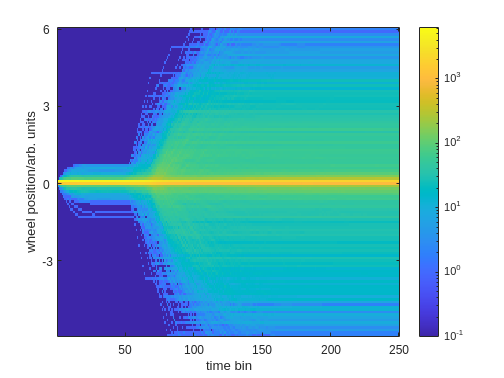

bins = [-6:0.1:6];
dd= datashader_image(data.wheel_pos, bins);
image(dd,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')
n_y_ticks = 5;
YTicks = [1:round(length(bins)/(n_y_ticks-1)):length(bins)];
YTickLabels = flip(bins(1:round(length(bins)/(n_y_ticks-1)):end));
set(gca, 'YTick',YTicks, 'YTickLabel',YTickLabels)    

ylabel('wheel position/arb. units')
xlabel('time bin')

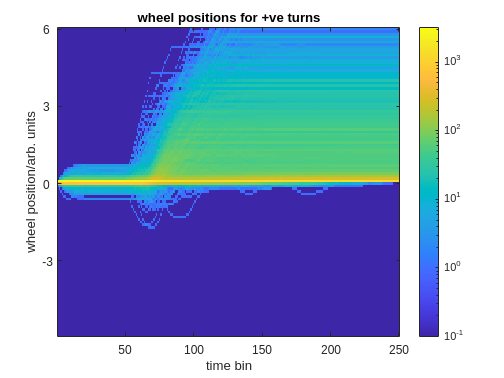

bins = [-6:0.1:6];
data_in = data{data.mean_wheel >0,'wheel_pos'};
dd= datashader_image(data_in, bins);
image(dd,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')
n_y_ticks = 5;
YTicks = [1:round(length(bins)/(n_y_ticks-1)):length(bins)];
YTickLabels = flip(bins(1:round(length(bins)/(n_y_ticks-1)):end));
set(gca, 'YTick',YTicks, 'YTickLabel',YTickLabels)    

ylabel('wheel position/arb. units')
xlabel('time bin')
title('wheel positions for +ve turns')

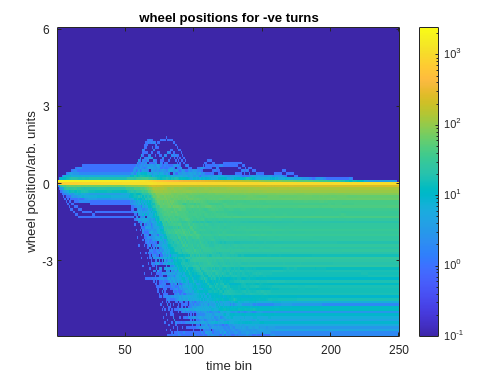


data_in = data{data.mean_wheel <0,'wheel_pos'};
dd= datashader_image(data_in, bins);
image(dd,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')
n_y_ticks = 5;
YTicks = [1:round(length(bins)/(n_y_ticks-1)):length(bins)];
YTickLabels = flip(bins(1:round(length(bins)/(n_y_ticks-1)):end));
set(gca, 'YTick',YTicks, 'YTickLabel',YTickLabels)    

ylabel('wheel position/arb. units')
xlabel('time bin')
title('wheel positions for -ve turns')

function shader_matrix= datashader_image(data_in, bins)
    
    ss =size(data_in);
    shader_matrix = zeros([length(bins)-1,ss(2)]);

    for i=1:ss(2)
        [n, edges]= histcounts(data_in(:,i),bins);
        shader_matrix(:,i) = n';
    end
    shader_matrix = flip(shader_matrix);

end

